%% Parameters van de bol
R = 5;      % straal in meters (5 cm)
N = 5;        % resolutie, hoe hoger N hoe meer punten

linspace(0, pi, N)

ans =          0    0.7854    1.5708    2.3562    3.1416


linspace(0, 2*pi, 2*N)

ans =          0    0.6981    1.3963    2.0944    2.7925    3.4907    4.1888    4.8869    5.5851    6.2832



%% Maak sferische coördinaten
[theta, phi] = meshgrid(linspace(0, pi, N), linspace(0, 2*pi, 2*N))

theta =          0    0.7854    1.5708    2.3562    3.1416
         0    0.7854    1.5708    2.3562    3.1416
         0    0.7854    1.5708    2.3562    3.1416
         0    0.7854    1.5708    2.3562    3.1416
         0    0.7854    1.5708    2.3562    3.1416
         0    0.7854    1.5708    2.3562    3.1416
         0    0.7854    1.5708    2.3562    3.1416
         0    0.7854    1.5708    2.3562    3.1416
         0    0.7854    1.5708    2.3562    3.1416
         0    0.7854    1.5708    2.3562    3.1416


phi =          0         0         0         0         0
    0.6981    0.6981    0.6981    0.6981    0.6981
    1.3963    1.3963    1.3963    1.3963    1.3963
    2.0944    2.0944    2.0944    2.0944    2.0944
    2.7925    2.7925    2.7925    2.7925    2.7925
    3.4907    3.4907    3.4907    3.4907    3.4907
    4.1888    4.1888    4.1888    4.1888    4.1888
    4.8869    4.8869    4.8869    4.8869    4.8869
    5.5851    5.5851    5.5851    5.5851    5.5851
    6.2832    6.2832    6.2832    6.2832    6.2832



%% Converteer naar cartesiaanse coördinaten
X = R * sin(theta) .* cos(phi)

X =          0    3.5355    5.0000    3.5355    0.0000
         0    2.7084    3.8302    2.7084    0.0000
         0    0.6139    0.8682    0.6139    0.0000
         0   -1.7678   -2.5000   -1.7678   -0.0000
         0   -3.3223   -4.6985   -3.3223   -0.0000
         0   -3.3223   -4.6985   -3.3223   -0.0000
         0   -1.7678   -2.5000   -1.7678   -0.0000
         0    0.6139    0.8682    0.6139    0.0000
         0    2.7084    3.8302    2.7084    0.0000
         0    3.5355    5.0000    3.5355    0.0000


Y = R * sin(theta) .* sin(phi);
Z = R * cos(theta);

%% Zet alles in een N*3 matrix
sphere_ptcld = [X(:), Y(:), Z(:)];

%% Verwijder eventueel dubbele rijen
sphere_ptcld = unique(sphere_ptcld, 'rows');

%% Stuur naar base workspace (voor gebruik in Simscape)20
assignin('base', 'sphere_ptcld', sphere_ptcld);

figure;
scatter3(sphere_ptcld(:,1), sphere_ptcld(:,2), sphere_ptcld(:,3), 20, 'filled');50

ans = 50

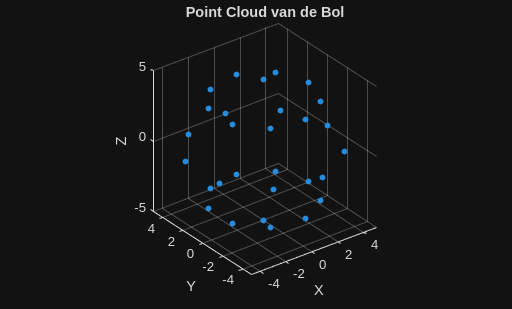

axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Point Cloud van de Bol');
grid on;